clc
clear
close all

Find most similar objects to files that existed in map set with 2D correlation.

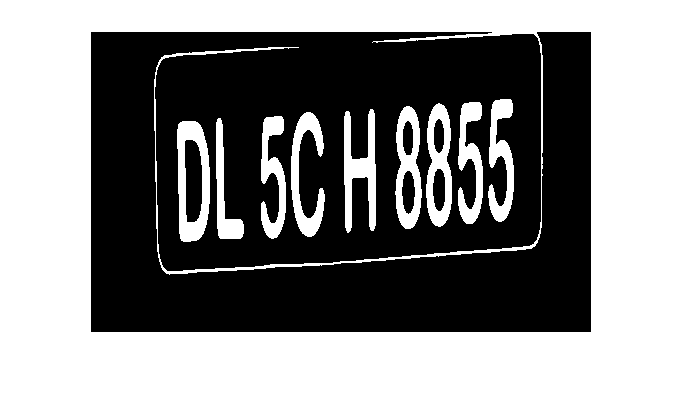

train = loadMap('Map Set');
[picture, cc] = openPlate();
picture = rgb2Bw(picture);
p1 = imgClean(picture, cc);
imshow(p1)


[L, Ne] = bwlabel(p1);
final_license = [];

for n = 1:Ne
    [r, c] = find(L == n);
    patchCrop = p1(min(r): max(r), min(c): max(c));
    patchCrop = imresize(patchCrop, [42, 24]);
    out = mapCorr(patchCrop, train);
    if out ~= -1
        final_license = [final_license cell2mat(train(2, out))];
    end
    
end
final_license

final_license = 'DL5CH8855'

loading map set into matlab

function train = loadMap(mapDir)
    di = dir(mapDir);
    name_temp = {di.name};
    name = name_temp(3:end);
    train = cell(2, length(name));
    for i = 1:length(name)
        train(1, i) = {imread(['Map Set', '\', cell2mat(name(i))])};
        temp = cell2mat(name(i));
        train(2, i) = { temp(1)};
    end
end

open test picture and resize that

function [p, cc] = openPlate()
    [file, path] = uigetfile(('*.jpg;*.bmp;*.png;*.tif'), "Please choose an image");
    picture = imread([path, file]);
    [~ , cc] = size(picture);
    p = imresize(picture, [300 500]);
end

Make the picture black and white

function p = rgb2Bw(picture)
    p = rgb2gray(picture);
end

Calculate threshhold and remove objects less than threshhold. complement picture and then remove small objects from picture

function p = imgClean(picture, cc)
    th = graythresh(picture);
    picture = ~imbinarize(picture, th);
    if cc > 2000 
        p = bwareaopen(picture, 350);
    else
        p = bwareaopen(picture, 200);
    end
end

correlation function

function out = mapCorr(img, train)
    total = size(train, 2);
    x = [];
    for k = 1:total
        y = corr2(train{1, k}, img);
        x(end+1) = y;
    end
    if max(x) > .5
        out = find(x == max(x));
    else
        out = -1;
    end
end